# Aproximando Sinais

## Onda quadradada com 50% de duty cycle   

Aproximaremos uma onda quadrada com 50% de duty cycle para uma senoide.

### Numericamente

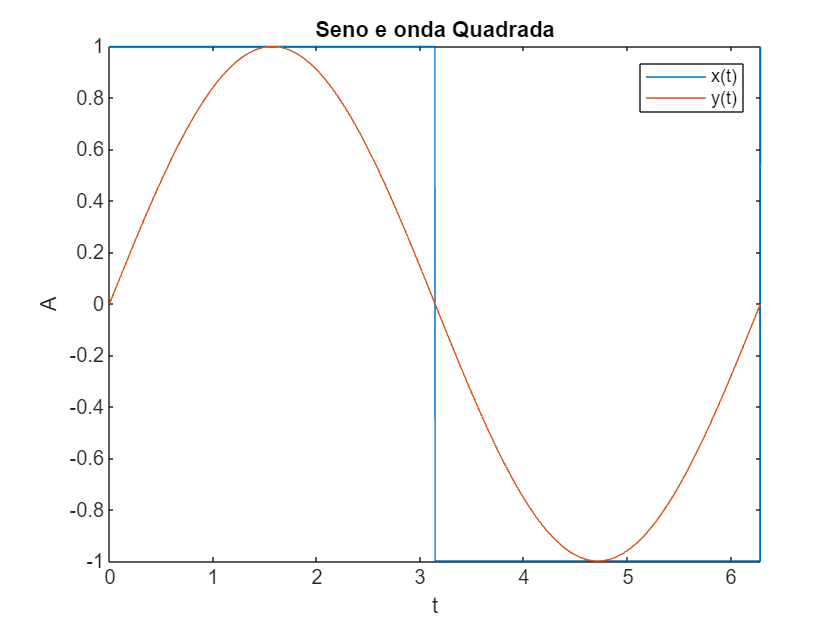

t = linspace(0, 2*pi, 2000); % vetor temporal: 100 pontos igualmente espaçados entre 0 e 2*pi
x = square(t); % Onda quadrada de 50% Duty e período 2*pi
y = sin(t); % Seno de período 2*pi
figure(1); % Figura 1
plot(t, x, t, y); % Plota os sinais
title("Seno e onda Quadrada"); % Título do gráfico
xlabel("t"); % Título do eixo das abscissas
ylabel("A");% Título do eixo das ordenadas
legend("x(t)", "y(t)") % Legenda
xlim([0 2*pi]); % Limita o intervalo do eixo x

e1 = trapz( (x-y).^2) % Erro cometido ao aproximar x para sin(t)

e1 = 453.2947

c = trapz(t, x.*y) / trapz(t, y.^2) % Cálculo do coeficente de correlação

c = 1.2732

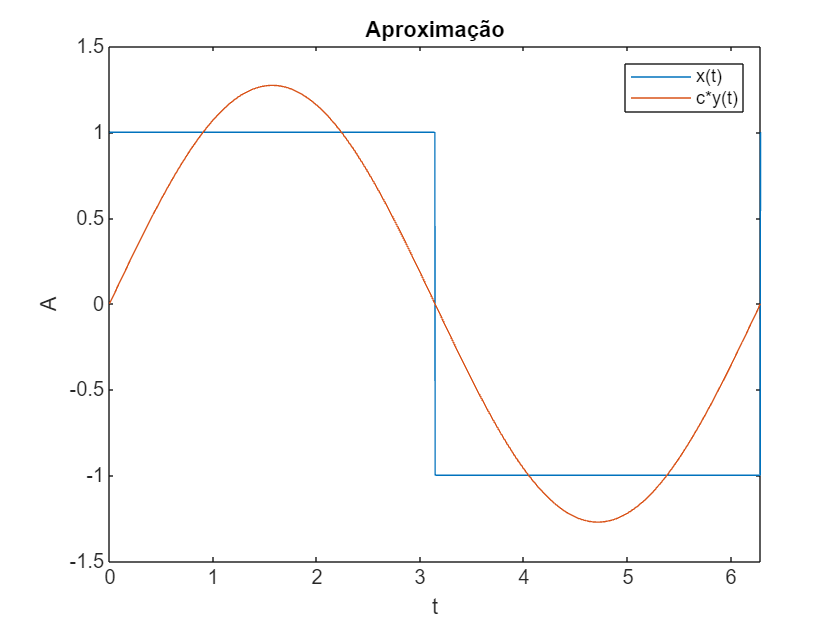

x_aprox = c*y; % Aproximação
figure(2); % Figura 2
plot(t, x, t, x_aprox); % Plota os sinais
title("Aproximação"); % Titulo do gráfico
xlabel("t"); % Título do eixo das abscissas
ylabel("A");% Título do eixo das ordenadas
legend("x(t)", "c*y(t)") % Legenda
xlim([0 2*pi]); % Limita o intervalo do eixo x

e2 = trapz( t, (x-x_aprox).^2) % Erro cometido ao aproximar x para c*sin(t)

e2 = 1.1902

### Analiticamente

syms t % Ambiente simbólico
x = piecewise(0 <= t < pi, 1, pi <= t < 2*pi, -1);  % Onda quadrada de 50% duty e período 2*pi
y = sin(t); % Seno de período 2*pi
c = int(x * y, t, 0, 2*pi) / int(y^2, t, 0, 2*pi) % Coeficiente de correlação

$$c = \frac{4}{\pi }$$

eval(c) % Valor

ans = 1.2732

## Onda quadrada - Caso geral

### Solução Numérica

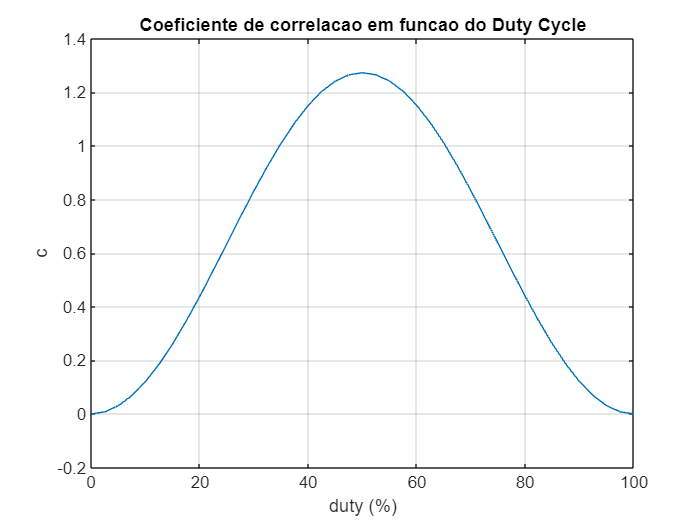

T = 2*pi; % Período
t = linspace(0, T, 1000); % Vetor temporal de 1000 pontos
y = sin(2*pi*t/T); % Seno
duty = 0:2.5:100; % Vetor de duty cycle (de 0% a 100% com passo de 2.5%)
for i = 1:length(duty) % Laço de repetição
    x = square(2*pi*t/T, duty(i)); % Onda quadrada para o i-ésimo duty cycle
    c(i) = trapz(t, x.*y) / trapz(t, y.^2); % Cálculo i-ésimo coeficente de correlação
    erro(i) = trapz(t, (x-c(i)*y).^2); % Erro na aproximação
end
figure(3); % Figura 3
plot(duty, c); % Plota c em função do duty cycle
title("Coeficiente de correlacao em funcao do Duty Cycle"); % Título do gráfico
xlabel("duty (%)"); % Título do eixo das abscissas
ylabel("c");% Título do eixo das ordenadas
grid on; % Habilita a vizualição da grade no gráfico

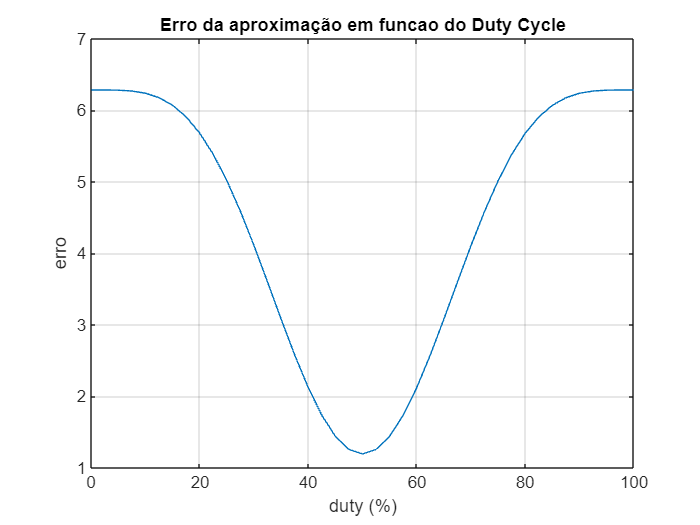

figure(4); % Figura 4
plot(duty, erro); % Plota o erro da aproximação em função do duty cycle
title("Erro da aproximação em funcao do Duty Cycle"); % Título do gráfico
xlabel("duty (%)"); % Título do eixo das abscissas
ylabel("erro");% Título do eixo das ordenadas
grid on; % Habilita a vizualição da grade no gráfico

### Solução Analítica

syms t T duty       % Ambiente simbolico
assume(t, "real"); % t pertence aos reais
assume(T, "real"); % T pertence aos reais
assumeAlso(T, "positive"); % T e maior que zero
assume(duty, "real"); % duty percente aos reais
assume(duty>0); % duty é maior que zero
assumeAlso(duty<1); % duty é menor que zero
assumptions % Suposições

$$ans = \left(\begin{array}{ccccc} T\in \mathbb{R} & t\in \mathbb{R} & 0<T & 0<\mathrm{duty} & \mathrm{duty}<1 \end{array}\right)$$

x = piecewise(0 <= t < T*duty, 1, T*duty <= t < T, -1);  % Onda quadrada
y = sin(2*pi*t/T); % Seno 
c = int(x*y, t, 0, T) / int(y^2, t, 0, T) % Coeficiente de correlação

$$c = \frac{4\,{\sin\left(\pi \,\mathrm{duty}\right)}^{2}}{\pi }$$

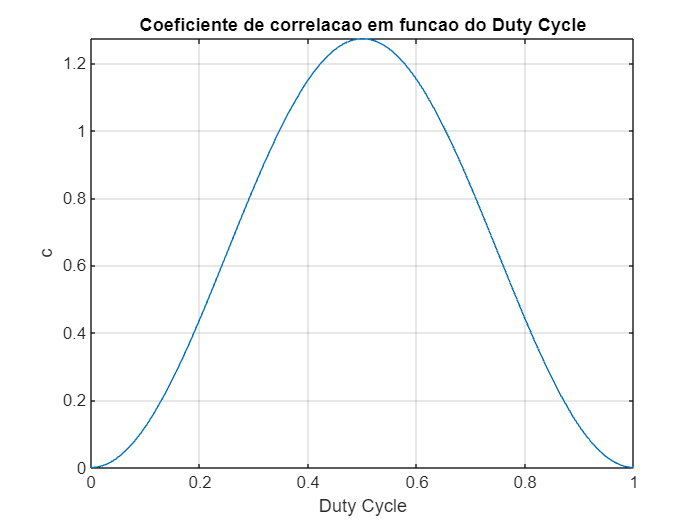

figure(3);
fplot(c); % Plotagem em ambiente simbólico
title("Coeficiente de correlacao em funcao do Duty Cycle");
xlabel("Duty Cycle");
ylabel("c");
grid on; % Habilita a grade